# Introduction

Implementation of mean-field interacting diffusions using sde_euler in SDETools. 


$$dY_{t}^{i} = \alpha\left(\frac{1}{N} \sum_{j=1}^{N} Y_{t}^{j} - Y_{t}^{i}\right)dt + \sigma_{i}dW_{t}^{i}$$


% Parallel pool
parpool('Processes')

# Baseline - Homogeneous Banks

Homogeneous banks ($N = 10, \mu = 1, \sigma = 1$), all-to-all coupling.

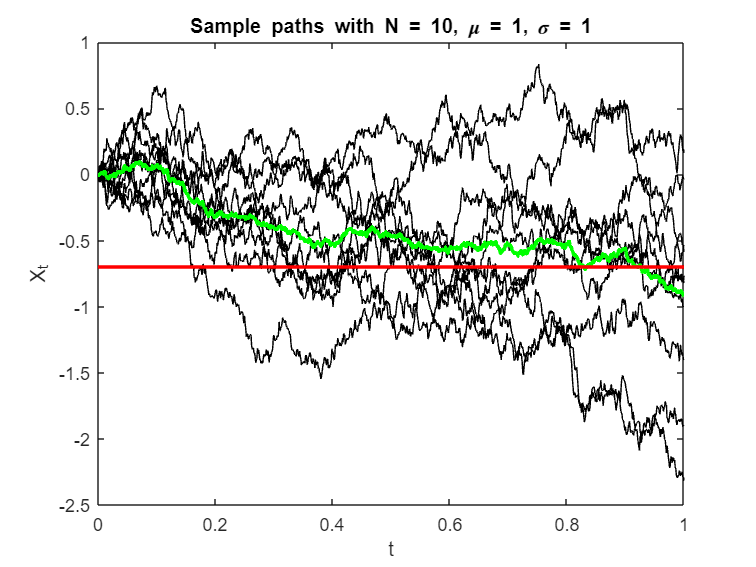

baseline = model(10, ones(10, 1), ones(10, 1));
baseline = baseline.sde_euler;
baseline = baseline.monte_carlo(5000);
baseline.plot_trajectory;
title("Sample paths with N = 10, \mu = 1, \sigma = 1");

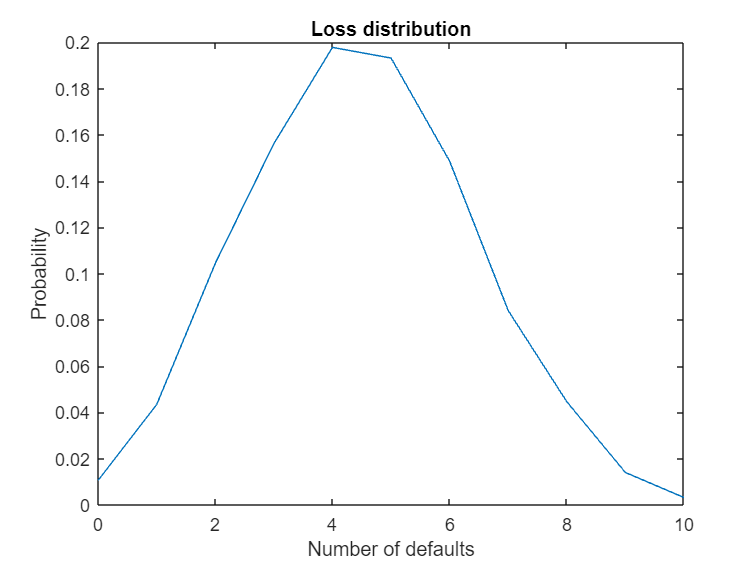

baseline.plot_loss

fprintf("Probability of systemic failure: %.2f", baseline.probfail);

Probability of systemic failure: 0.02

## Group A

groupA = model( ...
    10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );

groupA = groupA.sde_euler;
groupA = groupA.monte_carlo(5000);

Elapsed time is 20.521789 seconds.


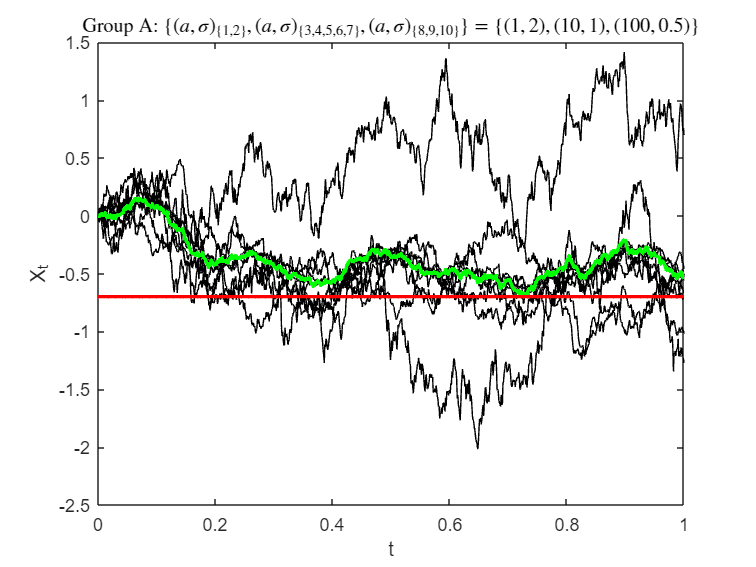

groupA.plot_trajectory;
title('Group A: $\left\{(\mu, \sigma)_{\left\{1, 2\right\}}, (\mu, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (\mu, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$', ...
'interpreter', 'latex');

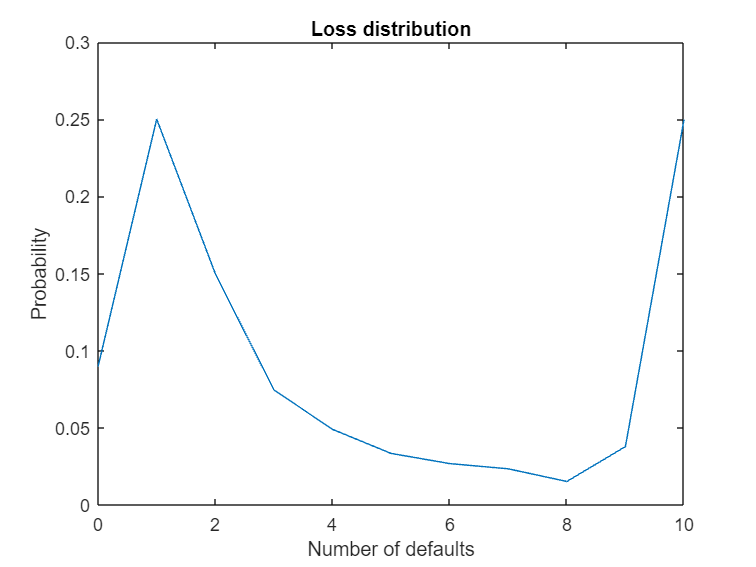

groupA.plot_loss;

fprintf("Probability of systemic failure: %.2f", groupA.probfail);

Probability of systemic failure: 0.30

## Group B

groupB = model( ...
    10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(0.5, 2, 1); repelem(1, 5, 1); repelem(2, 3, 1)] ...
    );

groupB = groupB.sde_euler;
groupB = groupB.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


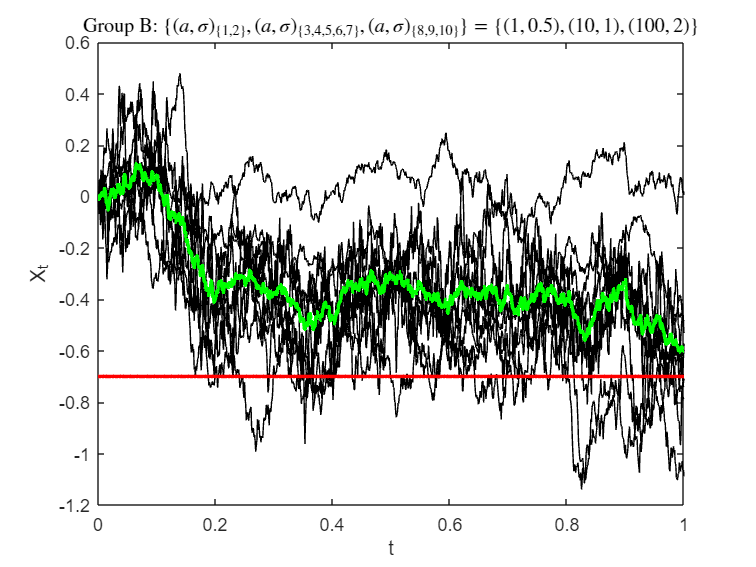

groupB.plot_trajectory;
title('Group B: $\left\{(\mu, \sigma)_{\left\{1, 2\right\}}, (\mu, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (\mu, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 0.5), (10, 1), (100, 2)\right\}$', ...
'interpreter', 'latex');

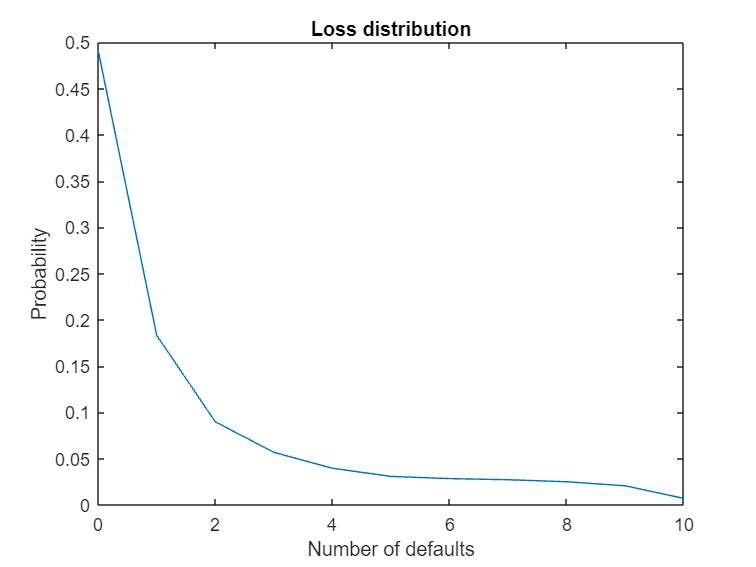

groupB.plot_loss;

fprintf("Probability of systemic failure: %.2f", groupB.probfail);

Probability of systemic failure: 0.02

## Group A Case 1: 8:1:1

groupA1 = model( ...
    10, ...
    [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)], ...
    [repelem(2, 8, 1); repelem(1, 1, 1); repelem(0.5, 1, 1)] ...
    );

groupA1 = groupA1.sde_euler;
groupA1 = groupA1.monte_carlo(5000);

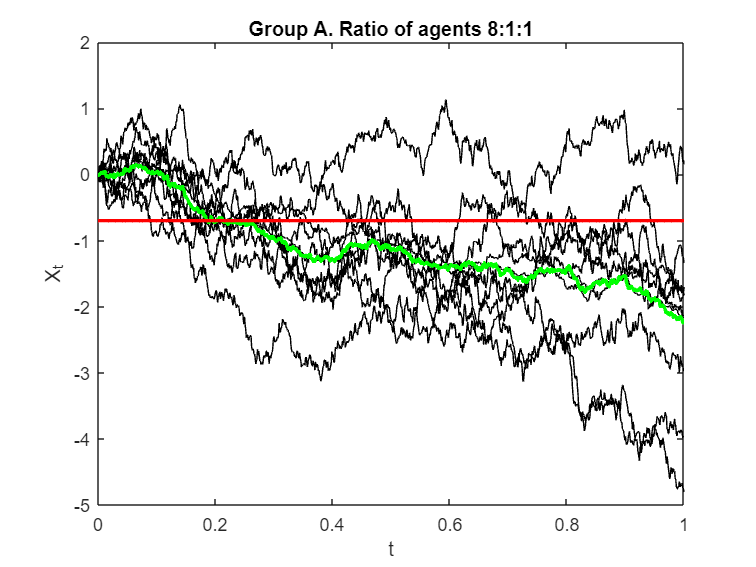

groupA1.plot_trajectory;
title('Group A. Ratio of agents 8:1:1');

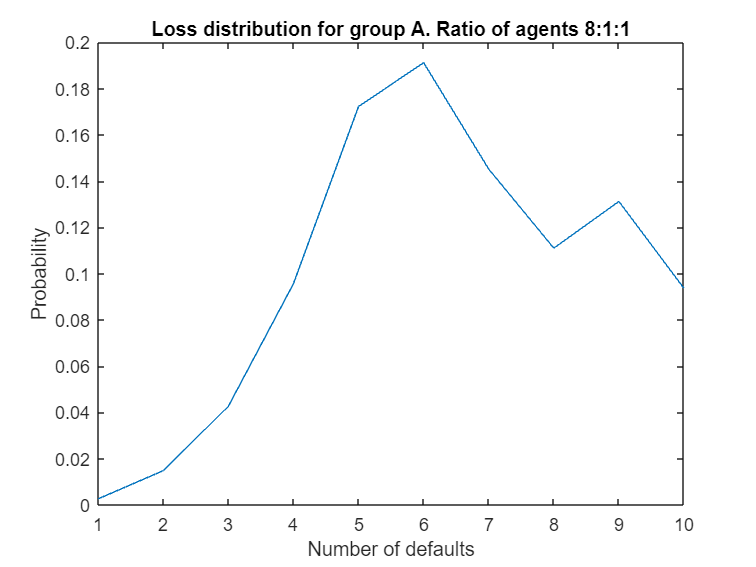

groupA1.plot_loss;
title('Loss distribution for group A. Ratio of agents 8:1:1');

fprintf("Probability of systemic failure: %.2f", groupA1.probfail);

Probability of systemic failure: 0.28

## Group A Case 2: 1:8:1

groupA2 = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(2, 1, 1); repelem(1, 8, 1); repelem(0.5, 1, 1)] ...
    );

groupA2 = groupA2.sde_euler;
groupA2 = groupA2.monte_carlo(5000);

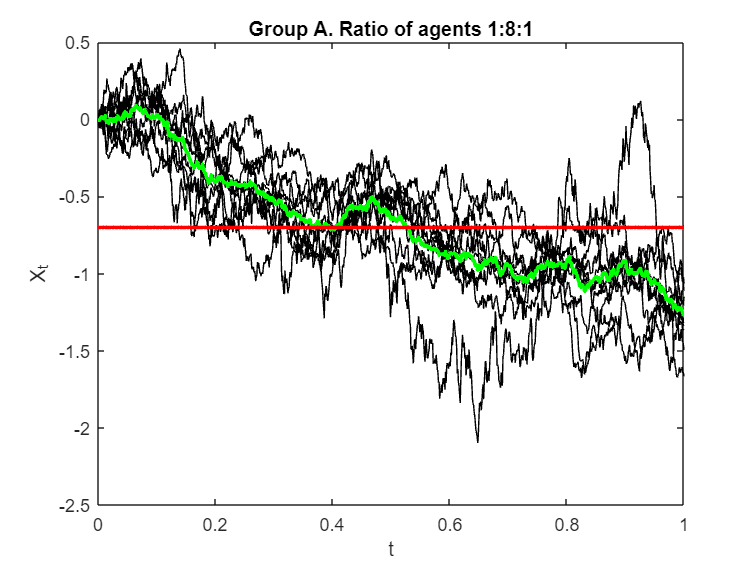

groupA2.plot_trajectory;
title('Group A. Ratio of agents 1:8:1');

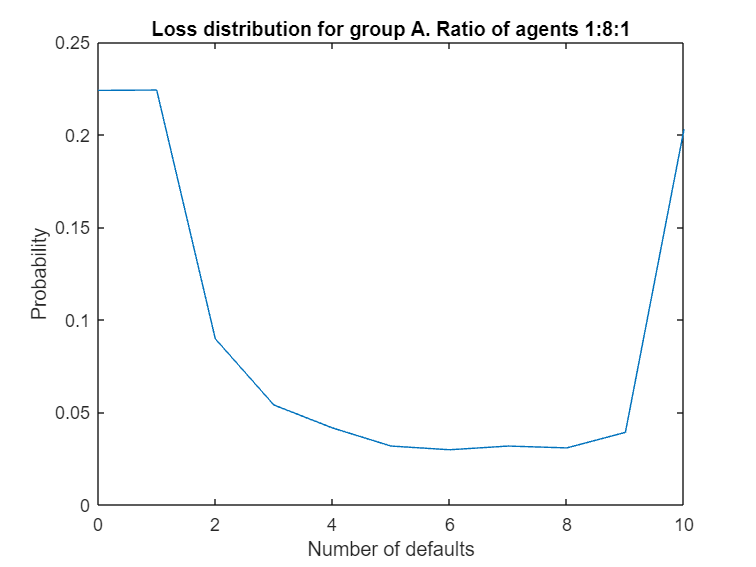

groupA2.plot_loss;
title('Loss distribution for group A. Ratio of agents 1:8:1');

fprintf("Probability of systemic failure: %.2f", groupA2.probfail);

Probability of systemic failure: 0.24

## Group A Case 3: 1:1:8

groupA3 = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)], ...
    [repelem(2, 1, 1); repelem(1, 1, 1); repelem(0.5, 8, 1)] ...
    );

groupA3 = groupA3.sde_euler;
groupA3 = groupA3.monte_carlo(5000);

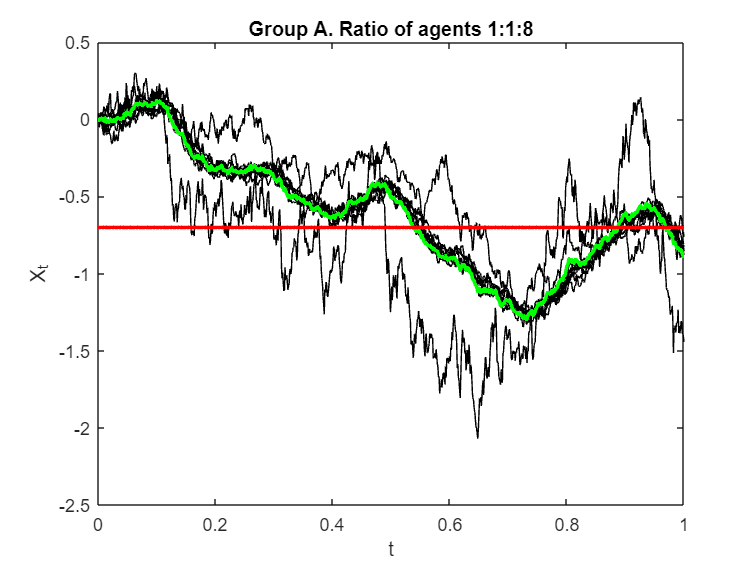

groupA3.plot_trajectory;
title('Group A. Ratio of agents 1:1:8');

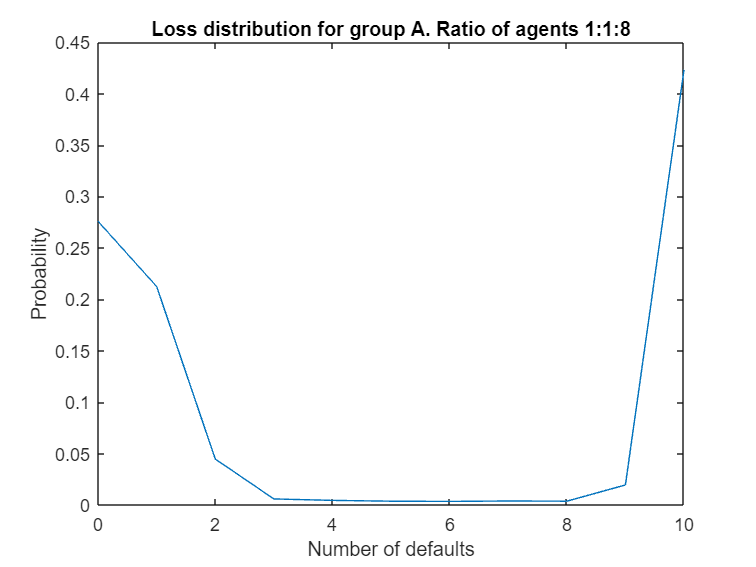

groupA3.plot_loss;
title('Loss distribution for group A. Ratio of agents 1:1:8');

fprintf("Probability of systemic failure: %.2f", groupA3.probfail);

Probability of systemic failure: 0.45

## Group B Case 1: 8:1:1

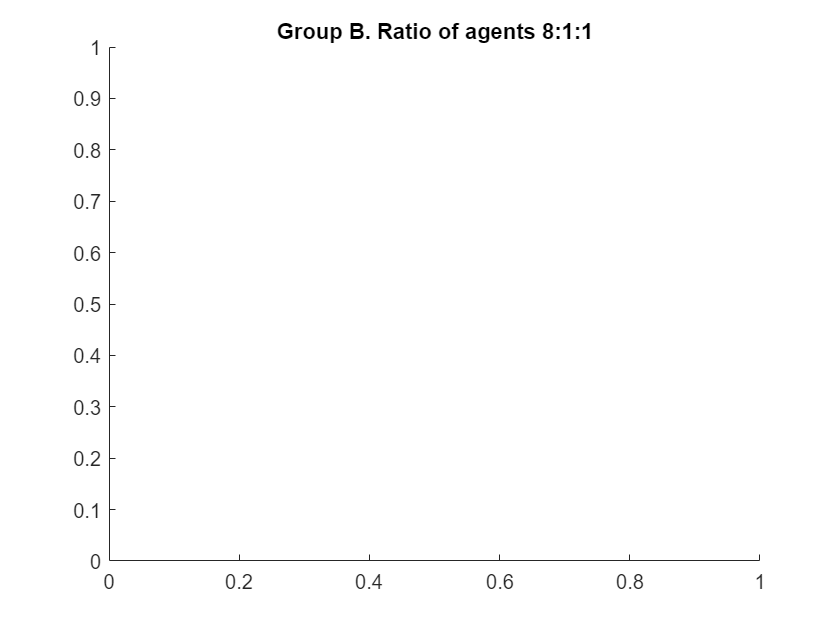

groupB1 = model( ...
    10, ...
    [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)], ...
    [repelem(0.5, 8, 1); repelem(1, 1, 1); repelem(2, 1, 1)] ...
    );

groupB1 = groupB1.sde_euler;
groupB1 = groupB1.monte_carlo(5000);

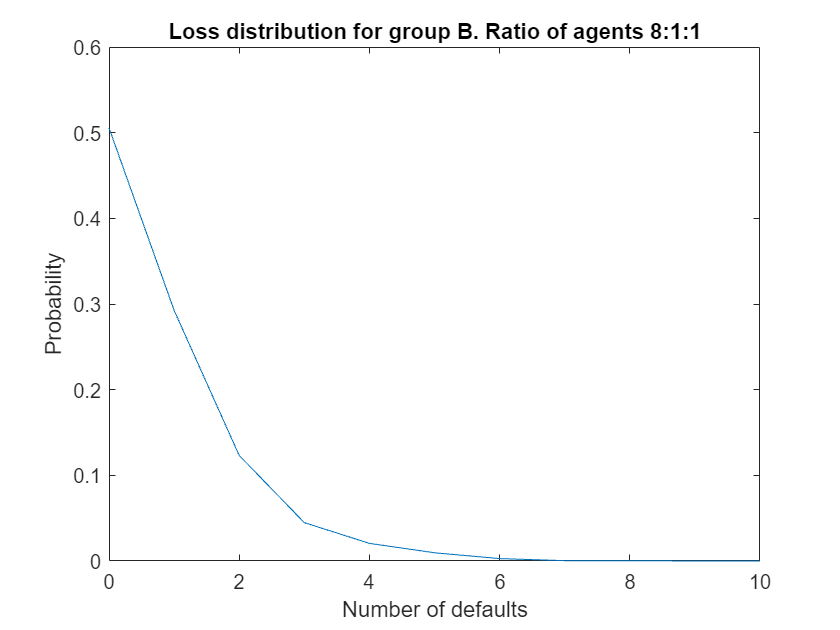

groupB1.plot_loss;
title('Loss distribution for group B. Ratio of agents 8:1:1');

fprintf("Probability of systemic failure: %.2f", groupB1.probfail);

Probability of systemic failure: 0.00

## Group B Case 2: 1:8:1

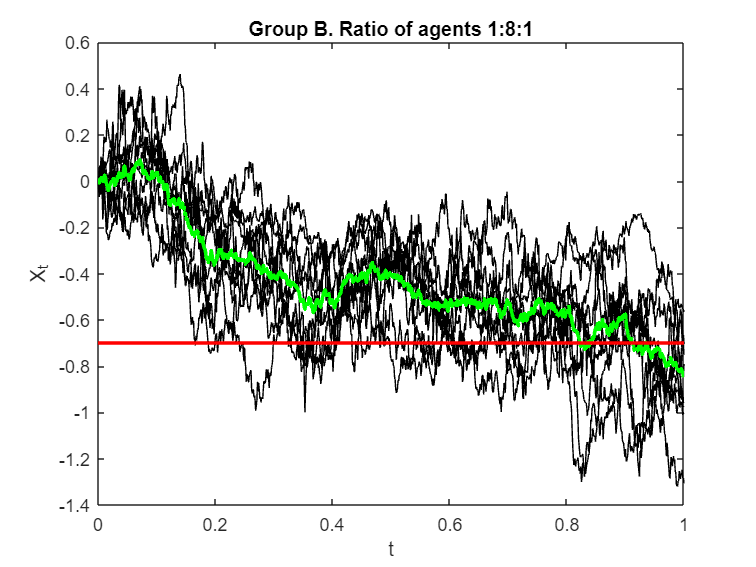

groupB2 = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(0.5, 1, 1); repelem(1, 8, 1); repelem(2, 1, 1)] ...
    );

groupB2 = groupB2.sde_euler;
groupB2 = groupB2.monte_carlo(5000);

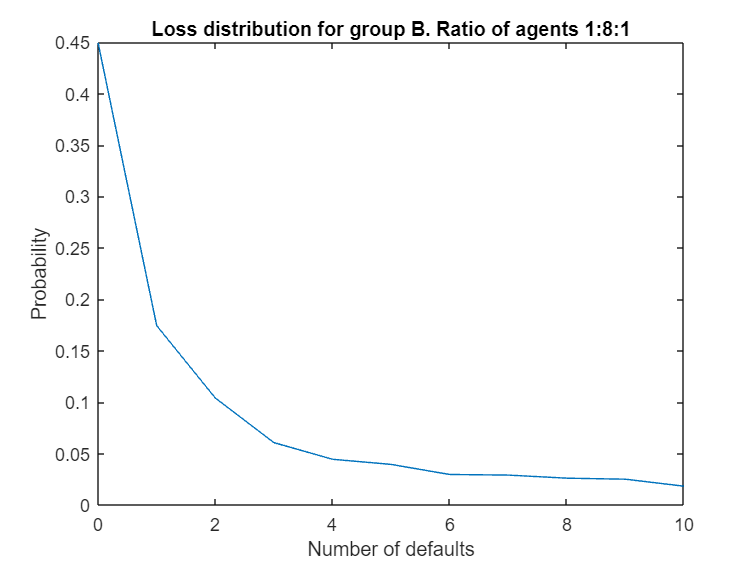

groupB2.plot_loss;
title('Loss distribution for group B. Ratio of agents 1:8:1');

fprintf("Probability of systemic failure: %.2f", groupB2.probfail);

Probability of systemic failure: 0.02

## Group B Case 3: 1:1:8

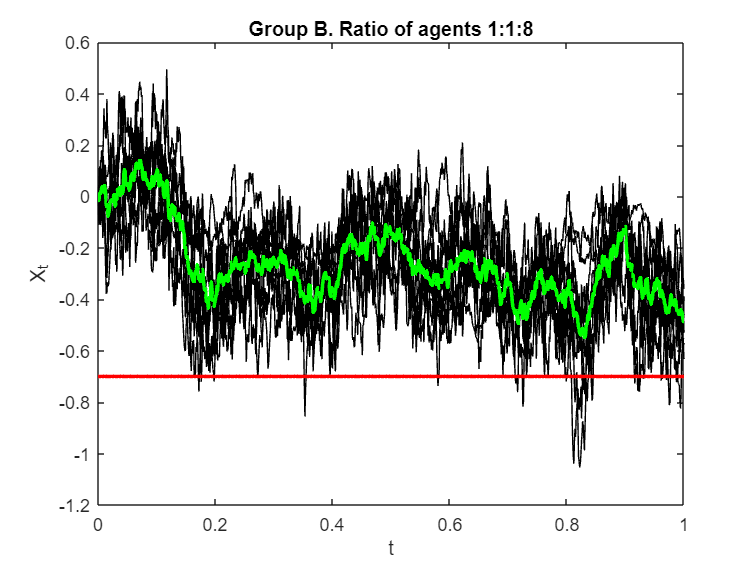

groupB3 = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)], ...
    [repelem(0.5, 1, 1); repelem(1, 1, 1); repelem(2, 8, 1)] ...
    );

groupB3 = groupB3.sde_euler;
groupB3 = groupB3.monte_carlo(5000);

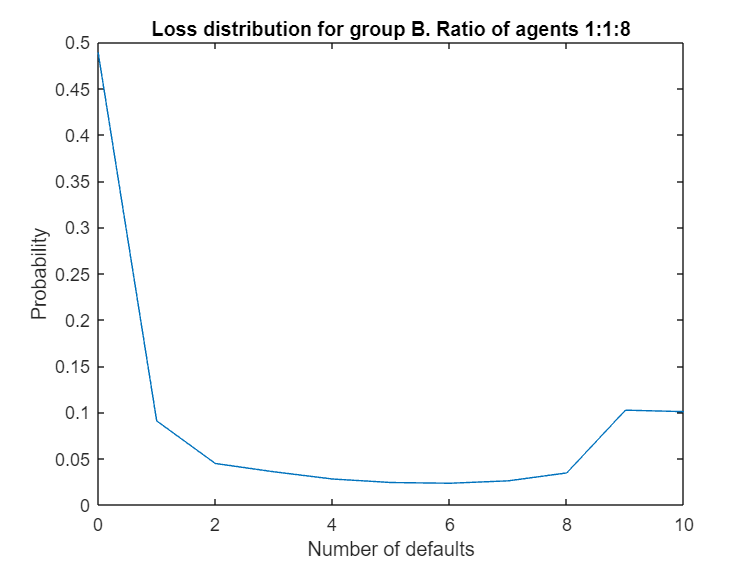

groupB3.plot_loss;
title('Loss distribution for group B. Ratio of agents 1:1:8');

fprintf("Probability of systemic failure: %.2f", groupB3.probfail);

Probability of systemic failure: 0.12

## Group A Case 1: 8:1:1 - Varying N

dt = 1e-3;
t = 0:dt:1; 
eta = -0.7;
% Simulate for different number of agents, from 10 to 300 with step 10.
Nvec = 10:10:300;      
repeats = 500; % Number of Monte-Carlo simulations
% Initialise variable to capture -1/N log P(A)
log_defaults = zeros(length(Nvec), 1);

% Loop over different number of agents
for N = Nvec
    y0 = zeros(N, 1);                           % Nx1 vector
    
    alpha = [repelem(1, 0.8.*N, 1); repelem(10, 0.1.*N, 1); repelem(100, 0.1.*N, 1)];
    sig = [repelem(2, 0.8.*N, 1); repelem(1, 0.1.*N, 1); repelem(0.5, 0.1.*N, 1)];
    f = @(t, y) alpha.*(mean(y) - y);
    g = @(t, y) sig;

    % Initialise variable to capture event A
    default = zeros(repeats, 1);

    % Loop to get probability of default
    for rep = 1:repeats
       opts = sdeset('RandSeed', rep);  
       y = sde_euler(f, g, t, y0, opts);     
       default(rep) = min(mean(y, 2)) <= eta;
    end

    log_defaults(N/10) = mean(default);
end

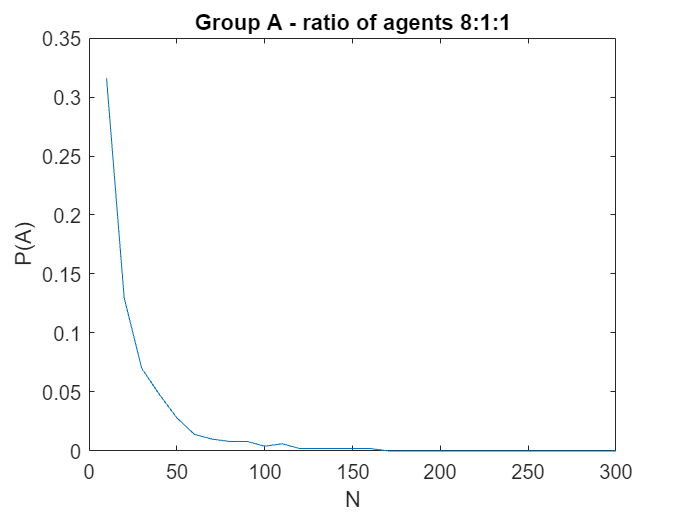

figure; 
plot(Nvec, log_defaults);
xlabel('N'); ylabel('P(A)');
title('Group A - ratio of agents 8:1:1')

## Group A Case 1: 1:1:8 - Varying N

dt = 1e-3;
t = 0:dt:1; 
eta = -0.7;
% Simulate for different number of agents, from 10 to 300 with step 10.
Nvec = 10:10:300;      
repeats = 500; % Number of Monte-Carlo simulations
% Initialise variable to capture -1/N log P(A)
log_defaults = zeros(length(Nvec), 1);

% Loop over different number of agents
for N = Nvec
    y0 = zeros(N, 1);                           % Nx1 vector
    
    alpha = [repelem(1, 0.1.*N, 1); repelem(10, 0.1.*N, 1); repelem(100, 0.8.*N, 1)];
    sig = [repelem(2, 0.1.*N, 1); repelem(1, 0.1.*N, 1); repelem(0.5, 0.8.*N, 1)];
    f = @(t, y) alpha.*(mean(y) - y);
    g = @(t, y) sig;

    % Initialise variable to capture event A
    default = zeros(repeats, 1);

    % Loop to get probability of default
    for rep = 1:repeats
       opts = sdeset('RandSeed', rep);  
       y = sde_euler(f, g, t, y0, opts);     
       default(rep) = min(mean(y, 2)) <= eta;
    end

    log_defaults(N/10) = mean(default);
end

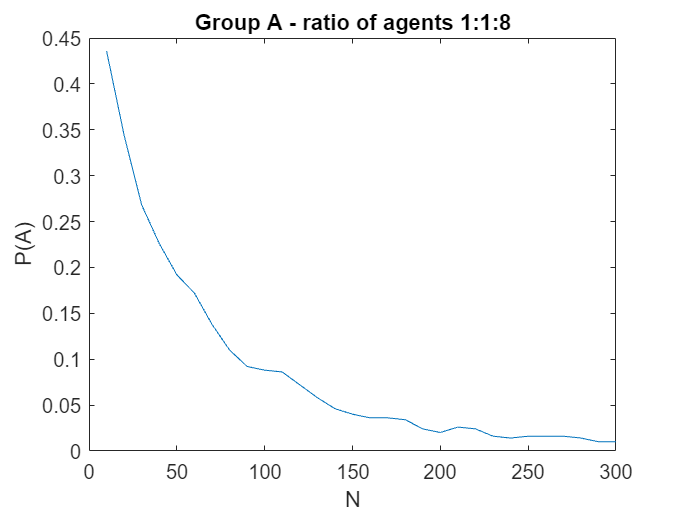

figure; 
plot(Nvec, log_defaults);
xlabel('N'); ylabel('P(A)');
title('Group A - ratio of agents 1:1:8')